Theoretical mapping of the kirigami disks

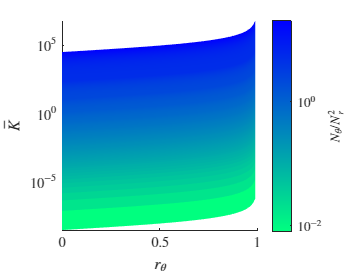

clear all; clc; close all;

%Defining variables


Nr = 1:1:50;
rtheta = linspace(0, 1, 100);
Ntheta = 2:1:20;

epsKC = ones(length(rtheta), length(Nr), length(Ntheta))*NaN;
Kbar = epsKC;
ell = epsKC;
Kbarell = epsKC;
fractal_length = epsKC;

f1 = figure();
hold on;
xlabel("$r_\theta$");
zlabel("$N_\theta/N_r^2$");
%ylabel("$\bar{K}$");
ylabel("$\bar{K}$");
set(gca, 'ColorScale', 'log')

X = zeros(length(Nr), length(rtheta));
Y = X;
Z = X;

for k = 1:length(Ntheta)
    for j = 1:length(Nr)
        x = [];
        y = [];
        for i = 1:length(rtheta)
            Nri = Nr(j); rthetaj = rtheta(i); Nthetak = Ntheta(k);
            Kbarijk = (24/pi^3)*(Nthetak^4/(Nri^6*(Nri+1)^2))*((1+rthetaj)/(1-rthetaj));
            ellijk = (pi/2)*(Nri*(Nri+1)/Nthetak)*((1-rthetaj)/(1+rthetaj));
            x(end+1) = (1+rthetaj)/(1-rthetaj); y(end+1) = Kbarijk;
            X(j,i) = rthetaj; Y(j,i) = Kbarijk; Z(j,i) = Nthetak/Nri^2;
        end
    end
    
    %pause(1);
end

contourf(X, Y, Z, 2000, 'EdgeColor', 'none');
colormap(flipud(winter));
% for j = 1:length(Nr)
%     for k = 1:length(Ntheta)
%         x = [];
%         y = [];
%         for i = 1:length(rtheta)
%             Nri = Nr(j); rthetaj = rtheta(i); Nthetak = Ntheta(k);
%             Kbarijk = (24/pi^3)*(Nthetak^4/(Nri^6*(Nri+1)^2))*((1+rthetaj)/(1-rthetaj));
%             ellijk = (pi/2)*(Nri*(Nri+1)/Nthetak)*((1-rthetaj)/(1+rthetaj));
%             x(end+1) = rthetaj; y(end+1) = Kbarijk;
%         end
%         plot(x, y, "color", "k");
%     end
%     %contourf(DX(:,:,k), RTHETA(:,:,k), fractal_length(:,:,k));
%     %pause(1);
% end



set(gca, 'YScale', 'log')
%set(gca, 'XScale', 'log')
set(gca, 'ColorScale', 'log')
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$N_\theta/N_r^2$';

f1.Units = "centimeters";
f1.Position = [1 1 10.25, 8.1];
figureSaver(f1, "bruteFigs/Kmap.pdf");